# Lag compensator design with Bode diagrams

This live script needs the control toolbox. Once profficient, students will probably find that the methods used in this script are mostly performed using sisotool. We also assume the students are already comfortable with the design procedures in the file: **proportional_design_with_bode.mlx**

This script assumes the following block diagram with system G(s) and compensator M(s). 

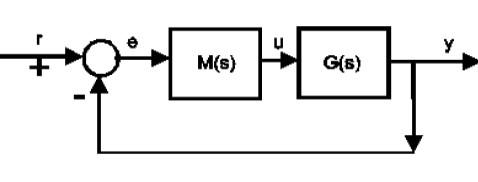

## Lag compensator properties 

The closed-loop transfer function is:   $G_c =\frac{\textrm{GM}}{1+\textrm{GM}}$ and the intention is to design the compensator M(s) to have the following stucture.


$$M\left(s\right)=K\frac{s+a}{s+\frac{a}{r}}$$
      

Core properties of this compensator are that the low frequency gain is 'r' times bigger than the high frequency gain and secondly, the system has negative phase in the regions near the corner frequencies: *a, a/r*. In order for the phase characteristic not to interfere with PM computations, the gain cross over frequency is a decade to the right of the zero, so $a=\frac{w_c }{10}$. 

$M\left(s\right)\;=\;K\left(\frac{s+a}{s+\frac{a}{r}}\right)\;\;\;=\;\;\;K\;\;\left(\frac{s+\frac{w_c }{10}}{s+\frac{w_c }{10r}}\right)$ ;                    $1\le r\le 10$.

The core characteristics are shown in the bode diagram here for: $M\left(s\right)=3\frac{s+1}{s+0\ldotp 2}$ . You can change the values in line 2 to show other examples.

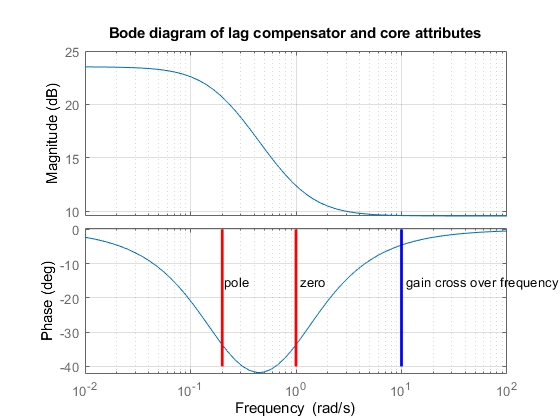

figure; clf
wc2=10; r=5; zero = -wc2/10;pole = zero/r;  K=3;
M2=tf(K*[1 -zero],[1 -pole]);
bode(M2,{wc2/1000,wc2*10});grid; hold on
plot([-pole,-pole],[-40,0],'r-','linewidth',2)
text(-pole*1.05,-15,'pole')
plot([-zero,-zero],[-40,0],'r-','linewidth',2)
text(-zero*1.1,-15,'zero')
plot([wc2,wc2],[-40,0],'b-','linewidth',2)
text(wc2*1.1,-15,'gain cross over frequency')
title('Bode diagram of lag compensator and core attributes')


disp('BELOW is SECTION 1')

BELOW is SECTION 1


disp(' ');

## Section 1: Design approach

Frequency response design of M(s) focuses on the gain and phase margins as core indicators of likely closed-loop behaviour and indeed, in practice, it is only the phase margin that is used actively.  In the following we set out 3 typical design criteria which can be used to underpin systematic design.

- phase margin.

- offset   (typically ramp offset criteria are used for convenience).

- bandwidth/cross-over frequency (not used in lag design).

## a) Phase margin as a core design parameter

Typical statements are that the expected damping ratio of the closed-loop is linked to the phase margin as given here.

disp('Links between PM, damping ratio and expected overshoot')

Links between PM, damping ratio and expected overshoot


damping_ratio = 0.4:.05:.9

damping_ratio =     0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000


overshoot = exp(-damping_ratio*pi./sqrt(1-damping_ratio.^2))

overshoot =     0.2538    0.2053    0.1630    0.1263    0.0948    0.0681    0.0460    0.0284    0.0152    0.0063    0.0015


PM =atan(2*damping_ratio./sqrt(-2*damping_ratio.^2+sqrt(1+4*damping_ratio.^4)))*180/pi

PM =    43.1176   47.6312   51.8273   55.6830   59.1873   62.3410   65.1564   67.6540   69.8600   71.8034   73.5137


One can determine the expected PM from desired overshoot or damping. So, given a desired overshoot of no more than 5-10% is common and thus a damping ratio of around 0.6, it is common to expect a PM of about 60 degrees to be  reasonable. More importantly, one expects that as the PM increases, damping increases and overshoot reduces so PM can also be used in a relative or incremental sense.

## b) Offset as a core design criteria

Offset in the closed-loop is an obvious indicator of performance. Commonly one will want an offset of zero which necessitates the compensator or system to include an integrator, altough in some cases non-zero offset may be acceptable where this relaxation allows better performance elsewhere.

**Offset to steps**: For a simple fbk loop with system G(s) and compensator M(s) and no integrator, offset to a constant unity reference is given by the formula: $e_{\textrm{ss}} =\frac{1}{1+G\left(0\right)M\left(0\right)}$

**Offset to ramps** can also be useful and is commonly used in books to help create more precise criteria to enable systematic/explicit design.This formula is only useful if the system DOES include an integrator. Offset to a unit ramp is given as: $e_{\textrm{ramp}} =\lim_{s\longrightarrow 0} \frac{1}{\textrm{sG}\left(s\right)M\left(s\right)}$

With a ramp and lag compensator, as given above, this formula reduces to:

$e_{\textrm{ramp}} =\lim_{s\longrightarrow 0} \frac{1}{\textrm{sG}\left(s\right)\textrm{Kr}}$;      $\lim_{s\longrightarrow 0} \textrm{sG}\left(s\right)=\alpha$

where, for convenience, we assume the integrator is within G(s) and needs cancelling out to determine the result. Given a desired value for the offset, the gain *Kr* is given from:


$$\textrm{Kr}=\frac{1}{\alpha e_{\textrm{ramp}} }$$


We deliberately keep the *K* and *r* together for now as these are both design parameters in the lag compensator which need to be selected.

disp('Illustration of ramp offset computations')

Illustration of ramp offset computations


G=tf(1,[1 5 6 0])

G =
 
          1
  -----------------
  s^3 + 5 s^2 + 6 s
 
Continuous-time transfer function.



eramp=0.2  

eramp = 0.2000

s = tf('s');
alpha = bode(minreal(s*G),0);
Kr=1/(alpha*eramp)

Kr = 30.0000


disp('BELOW is SECTION 2')

BELOW is SECTION 2


disp(' ');

## c) Bandwidth as a design criteria - not used for lag design

A lag compensator is a low gain design approach which focuses on managing damping and offset and as such does not have capacity or degrees of freedom to simultaneoulsy manage the bandwidth. In simple terms, having dealt with the former 2 criteria, you have to accept whatever bandwidth results.

## Section 2: Simple lag design using phase margin and ramp offset criteria

For this section, assume the system includes an integrator so that the offset to constant targets is zero. We want to design the parameters of the compensator M(s) so that we have a desirable phase margin and also to manage the offset to ramp targets. The process can be systemised as follows into two key steps:

- First use a simple proportional design *K* to achieve the desired phase margin.

- Second, add a lag compensator component $\left(\frac{s+a}{s+\frac{a}{r}}\right)$ to meet the ramp offset criteria.

Note, as mentioned above the full compensator structure reduces to this:


$$M\left(s\right)\;\;=\;\;\;K\left(\frac{s+a}{s+\frac{a}{r}}\right)\;\;\;=\;\;\;K\;\;\left(\frac{s+\frac{w_c }{10}}{s+\frac{w_c }{10r}}\right)$$
 

**CRITERIA 1**: A reminder of the of simple proportional design (**proportional_design_with_bode.mlx) **is given here.

- Decide desired PM and call this $\phi \ldotp$

- The PM is computed at the gain cross over frequency, so we can easily determine the frequency $w_c$ such that: $\arg \left(\textrm{GM}\right)=-180+\phi$. ***MANUAL ENTRY of ***$w_c$ ***REQUIRED (so some approximation inevitable)!***

- Then chose the proportional *K* so that: $\left|\textrm{KG}\left(jw_c \right)\right|=1$ and thus $w_c$ will become the gain cross over frequency.

- Recall that the parameter *a* in the compensator is defined as $a=\frac{w_c }{10}$.

**CRITERIA 2**: Next, we need to consider the ramp offset criteria; this is achieved by adding the lag component. From section 1b above, the required *Kr* is given from: $\textrm{Kr}=\frac{1}{\alpha e_{\textrm{ramp}} }$ where $\lim_{s\longrightarrow 0} \textrm{sG}\left(s\right)=\alpha$. Note, however, that  *K* has already been chosen through CRITERIA 1 which means we can now uniquely determine *r*.

## Example 1

The procedure will be clear following some illustration here. 

STEP 1: Data entry G(s) and definition of target PM and production of base line bode diagram.

G=tf(1,[1 5 8 0]);
desiredPM = 60;
wmin=0.01;
wmax=10;
figure; clf
bode(G,{wmin,wmax});grid;hold on
plot([wmin,wmax],[-180+desiredPM]*[1 1],'r')
text(wmin*10,-180+desiredPM+10,'-180+\phi')

STEP 2: Determine the required gain cross over frequency $w_c$ to achieve the target PM; you can edit $w_c$ on the code line below. **Make sure the green line crosses the intersect between the blue and red lines.** Re-run section to update the plot and ensure your choice for $w_c$ is correct.

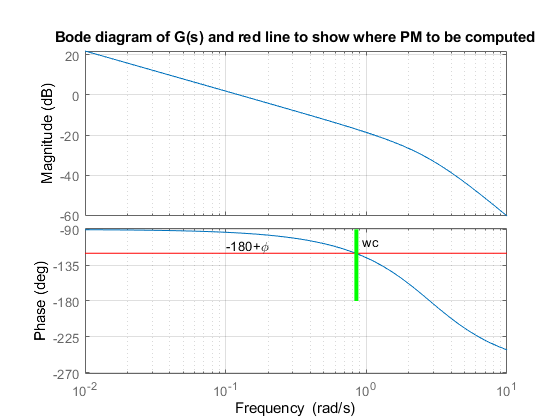

wc=0.85; %% Edit the wc value here
plot([wc,wc],[-180,-90],'g','linewidth',3)
text(wc*1.1,-180+desiredPM+15,'wc')
title(['Bode diagram of G(s) and red line to show where PM to be computed'])

disp('*****************************************')

*****************************************


disp(['Identified a suitable wc as ',num2str(wc),'rad/s'])

Identified a suitable wc as 0.85rad/s


STEP 3: Determine the required gain *K* here. If $w_c$ is computed correctly above, then the red compensated line will have $w_c$ as its gain cross over frequency, that is the intersect of the red and green line will be at 0dB. **Reminder that the phase diagram above is unchanged when we simply scale with a gain *****K*****.**

disp('*****************************************')

*****************************************


disp('Proportional design')

Proportional design


K=1/bode(G,wc)

K = 7.1635

K_in_DB = 20*log10(K)

K_in_DB = 17.1025

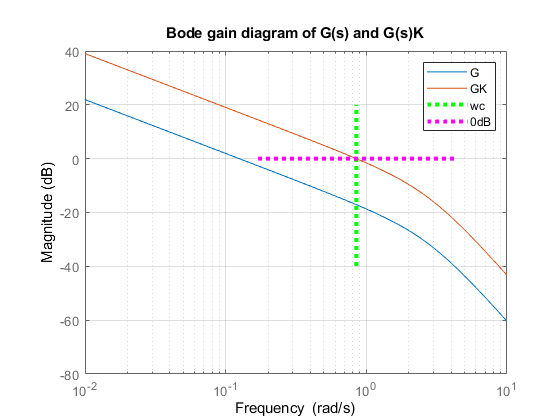

figure; clf
bodemag(G,G*K,{wmin,wmax});grid;hold on
plot([wc,wc],[-40,20],'g:','linewidth',3)
plot([wc/5,wc*5],[0,0],'m:','linewidth',3)
title(['Bode gain diagram of G(s) and G(s)K'])
legend('G','GK','wc','0dB')

STEP 4: Finally add the lag component by determining the required value for *r* using CRITERIA 2, or the formula: $\textrm{Kr}=\frac{1}{\alpha e_{\textrm{ramp}} }$ . This requires the desired ramp offset to be defined and realistic. Typically we need: $1\le r\le 10$. If this is not satisfied then either the PM and/or the ramp error criteria need relaxing.

disp('*****************************************')

*****************************************


disp('Ramp error criteria and whole compensator')

Ramp error criteria and whole compensator


disp('and final bode diagram and margins')

and final bode diagram and margins


eramp=0.2

eramp = 0.2000

disp(['Crossover frequency is ',num2str(wc)])

Crossover frequency is 0.85


s = tf('s');
alpha = bode(minreal(s*G),0);
r=1/(alpha*eramp*K)

r = 5.5839


M = tf(K*[1,wc/10],[1,wc/(10*r)])

M =
 
  7.163 s + 0.6089
  ----------------
    s + 0.01522
 
Continuous-time transfer function.



disp(['Target phase margin was ',num2str(desiredPM)])

Target phase margin was 60


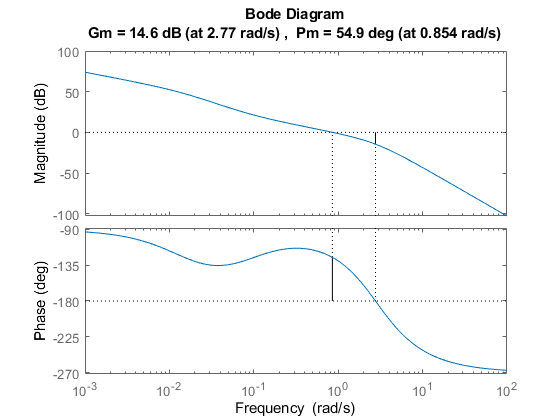

figure; clf
margin(G*M)

If the design is correct, you would expect the compensated system to have:

- A PM slightly less than the target PM (due to the negative phase in the lag).

- A cross over frequency close to the one specified in step 2 above.

- The simple proportional design is also overlaid so the differences in gain at low frequency can be viewed [note that phase(G)=phase(GK)].

- The phase dip should be well to the left (about a decade) of the gain cross-over frequency.

disp('*****************************************')

*****************************************


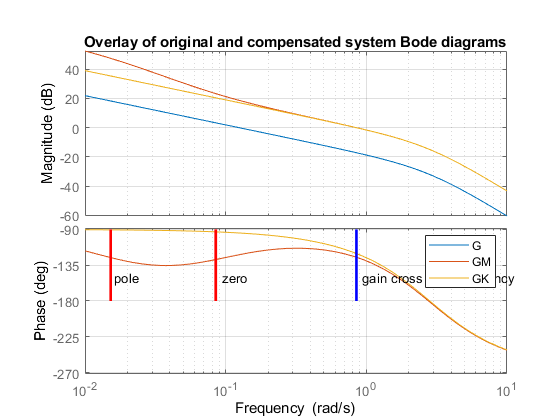

figure; clf
pole = -wc/(r*10); zero = -wc/10;
bode(G, G*M,G*K,{wmin,wmax});grid; hold on
plot([-pole,-pole],[-180,-90],'r-','linewidth',2)
text(-pole*1.05,-150,'pole')
plot([-zero,-zero],[-180,-90],'r-','linewidth',2)
text(-zero*1.1,-150,'zero')
plot([wc,wc],[-180,-90],'b-','linewidth',2)
text(wc*1.1,-150,'gain cross over frequency')
legend('G','GM','GK')
title('Overlay of original and compensated system Bode diagrams')


disp('BELOW is SECTION 3')

BELOW is SECTION 3


disp(' ');

### Section 3: Remarks and student independent study

- The resulting PM is less than the desired PM due to the phase lag characteristic; that should be clear in the last figure which overlays the bode of G and GM and shows the phase for GM is slightly less at the gain cross over frequency.  Typical guidance would be to set the target PM in step 2 (CRITERIA 1) to be about 5 degrees higher so that the resultant PM once the design is complete is closer to the desired value.

- One should note that the choice of PM  never had a precise link with damping/behaviour in the first place, and thus some fine tuning will typically be required anyway.

- Typical text books assume an integrator is already in the system and use a ramp error criteria to make the design precise. Alternatively, one could consider a scenario where there was no integrator present and one was aiming for a given offset to a constant target (see section 1b). The required algebra is slightly more involved but not much.

Step responses are included below for completeness. Here the lag seems to be worse than simple proportional, and indeed does have a worse PM and a very slow pole hence the slow convergence. However, remember the lag was used to improve low frequency gain for ramp targets, and thus the benefits will not be clear in a step response.

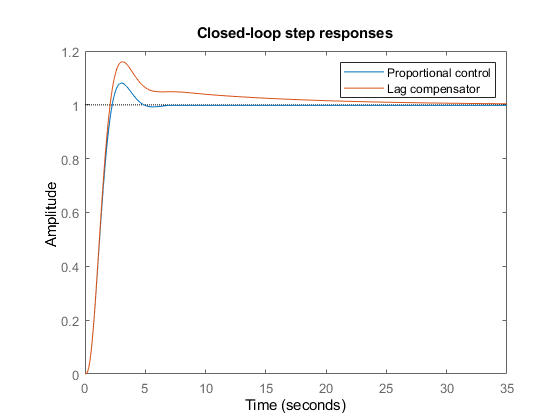

figure;clf
GcK = feedback(G*K,1);
GcM=feedback(G*M,1);
step(GcK,GcM);
title('Closed-loop step responses')
legend('Proportional control','Lag compensator')